Section 1: Raised-Cosine Generation

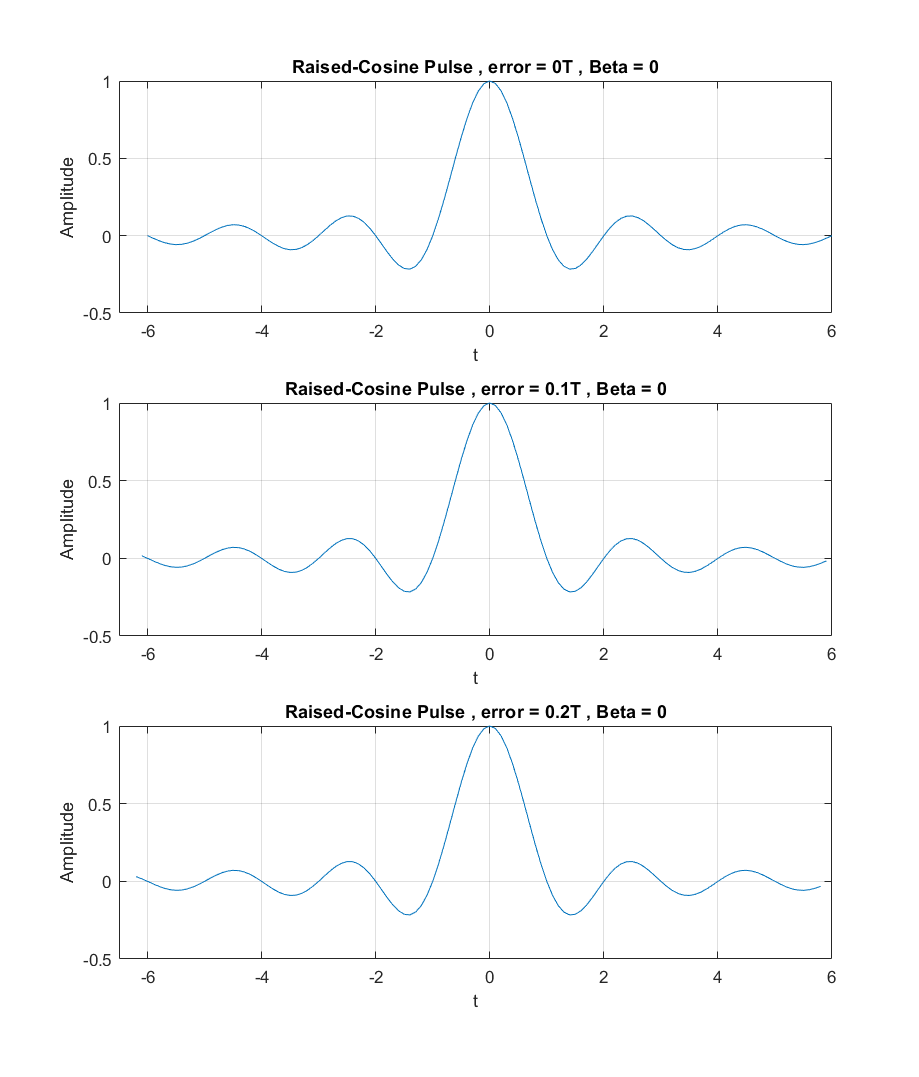

T = 1;
Fs = 10;
% beta can change according too given data 
B = 0;
sampling_error  = [0,0.1*T,0.2*T];
start = -6*T;
ending = 6*T;
len = (ending - start)*Fs + 1;
t = zeros(3, len);
pulse = zeros(3, len);
figure1=figure('Position', [100, 100, 1024, 1200]);
for i = 1:3
    [t(i,:), pulse(i,:)] = RC_pulse(T, Fs, B, sampling_error(i), start, ending);
    subplot(3,1,i);
    plot (t(i,:),pulse(i,:));
    title("Raised-Cosine Pulse , error = " + sampling_error(i)/T + "T"+ ...
        " , Beta = " + B);
    xlabel('t');
    ylabel('Amplitude');
    xlim([-6.5 6]);
    grid on;
end

Section 2: Signal Generation

N = 10e5;
bits = randi([0,1], 1, N);

modulated_symbols = zeros(1,length(bits));

for i=1:length(bits)
    if ( bits(1,i) == 1 )
        modulated_symbols(1, i) = 1 ;
    else
        modulated_symbols(1, i) = -1;
    end
end

upsampled_symbols = upsample(modulated_symbols, T*Fs);
upsampled_symbols = upsampled_symbols(1 : (end - ( T*Fs -1)));

transmitted_signal = zeros(3, (length(upsampled_symbols)+length(pulse)-1));
for i = 1:3
transmitted_signal(i,:) = conv(upsampled_symbols, pulse(i,:)) ;
end

Section 3: Noise Generation and AWGN Channel Modeling

SNR_dB = 0:10;
Eb = 1;
SNR_i = 0 ;
eta = zeros(1,length(SNR_dB));
for i=1:length(SNR_dB)
    SNR_i = (10)^(SNR_dB(1,i)/10) ;
    eta(1,i) = Eb/SNR_i ;
end

noise = randn(1,length(transmitted_signal(1,:)));
noise = diag(sqrt(eta./2))*repmat(noise,11,1);

received_signal1 = repmat(transmitted_signal(1,:),11,1)+ noise;
received_signal2 = repmat(transmitted_signal(2,:),11,1)+ noise;
received_signal3 = repmat(transmitted_signal(3,:),11,1)+ noise;

Section 4: Symbol Detection

L = T * Fs;
T_sampling = 6*L + 1 : L : (N+6-1)*L + 1 ;

samples1 = received_signal1(:,T_sampling);
samples2 = received_signal2(:,T_sampling);
samples3 = received_signal3(:,T_sampling);

detected_symbols1 = symbol_detection(samples1 ,N);
detected_symbols2 = symbol_detection(samples2 ,N);
detected_symbols3 = symbol_detection(samples3 ,N);


Section 5: Error Probability Calculation

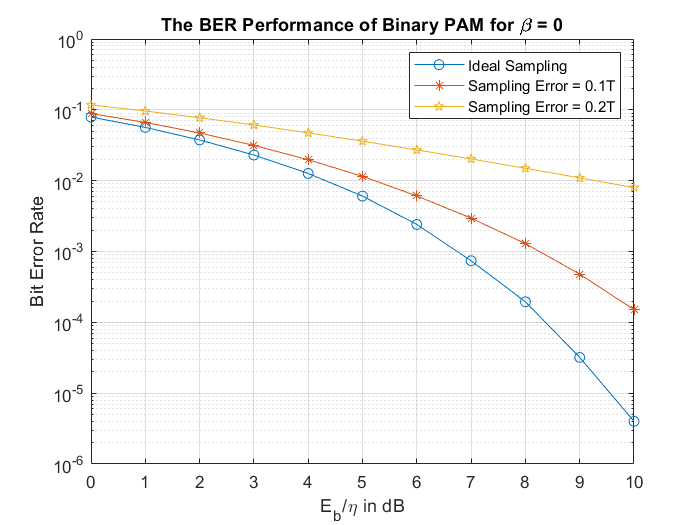

repeated_symbols = repmat(modulated_symbols,11,1);

P_e1 = Error_probability(repeated_symbols, detected_symbols1, N);
P_e2 = Error_probability(repeated_symbols, detected_symbols2, N);
P_e3 = Error_probability(repeated_symbols, detected_symbols3, N);

figure
semilogy(SNR_dB, P_e1 ,'-o' ,SNR_dB ,P_e2,'-*' ,SNR_dB ,P_e3,'-p')
grid on
title("{The BER Performance of Binary PAM for \beta = " + B + "}")
xlabel('{E_b}/\eta in dB');
ylabel('Bit Error Rate')
legend('Ideal Sampling','Sampling Error = 0.1T','Sampling Error = 0.2T')

Functions:

function [t , Pulse] = RC_pulse(T, Fs, B, sampling_error, start, ending)

t = (start*Fs:ending*Fs)/Fs-sampling_error;
% display(t)
Pulse = zeros(1,length(t));

for i = 1 : length(t)
   if ( (t(1,i) == -T/(2*B) ) || ( t(1,i) == T/(2*B) ) )
       Pulse(1,i) = (pi/4)*sinc(1/(2*B));
   else 
       Pulse(1,i) = (cos(pi*B*t(1,i)/T).*sinc(t(1,i)/T))./((1-(2*B.*t(1,i)./T).^2));
   end
   
end
end

function [detected_symbols] = symbol_detection(samples ,N)
detected_symbols = zeros(11,N);

pos = samples >= 0;
neg = samples < 0;
detected_symbols(pos) = 1;
detected_symbols(neg) = -1;
end

function Pe = Error_probability(repeated_symbols, detected_symbols, N)
num_errors = sum((repeated_symbols ~= detected_symbols),2);
Pe = reshape(num_errors, [1 11])/N;
end
